clear
clc

t = open("t.mat");
t = t.t;

h0 = open("h0.mat");
h0 = h0.h;
h10 = open("h10.mat");
h10 = h10.h;
h20 = open("h20.mat");
h20 = h20.h;
h40 = open("h40.mat");
h40 = h40.h;
h60 = open("h60.mat");
h60 = h60.h;
h72 = open("h72.mat");
h72 = h72.h;
href = open("href.mat");
href = href.href;

hc = open("hcombine.mat");
hc = hc.h;


u0   = open("u0.mat");
u0   = u0.u;
u10   = open("u10.mat");
u10   = u10.u;
u20  = open("u20.mat");
u20  = u20.u;
u40  = open("u40.mat");
u40  = u40.u;
u60  = open("u60.mat");
u60  = u60.u;
u72  = open("u72.mat");
u72  = u72.u;
uref = open("uref.mat");
uref = uref.uref;

uc = open("ucombin.mat");
uc = uc.u;


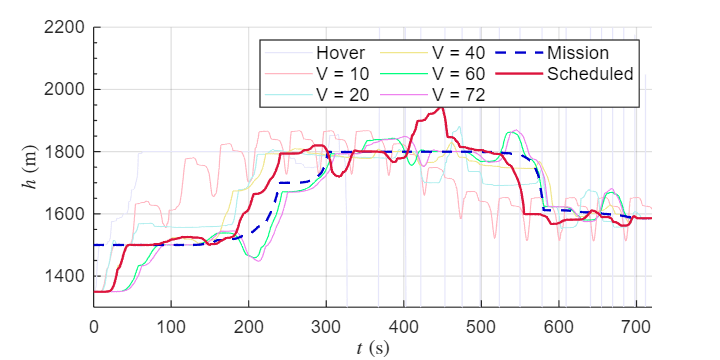

% 3 Compute step response characteristics

figure(1)

plot(linspace(0, 720, numel(h0))', h0, '-', 'Color', [230/255 230/255 250/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(h10))', h10, '-', 'Color', [255/255 182/255 193/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(h20))', h20, '-', 'Color', [175/255 238/255 238/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(h40))', h40, '-', 'Color', [240/255 230/255 140/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(h60))', h60, '-', 'Color', [0/255 255/255 127/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(h72))', h72, '-', 'Color', [238/255 130/255 238/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(href))', href, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(linspace(0, 720, numel(hc))', hc, '-','Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 720]);
ylim([1300 2200]);

% Legends
legend("Hover", "V = 10", "V = 20", "V = 40", "V = 60",  "V = 72", "Mission", "Scheduled", 'NumColumns', 3, FontSize = 11.5)

xlabel('$t \; (\mathrm{s})$', 'Interpreter', 'latex');
ylabel('$h \; (\mathrm{m})$', 'Interpreter', 'latex');
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 600 300]);

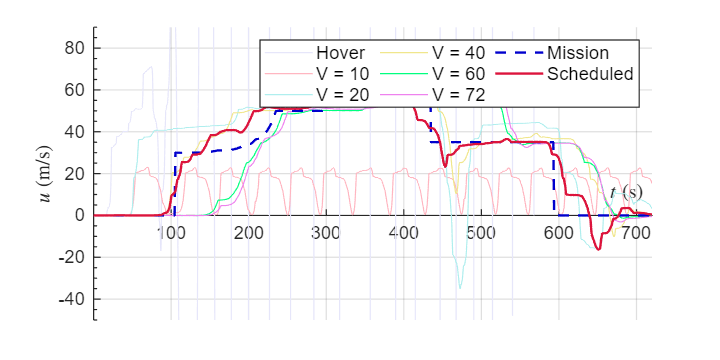

figure(2)

plot(linspace(0, 720, numel(u0))', u0, '-', 'Color', [230/255 230/255 250/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(u10))', u10, '-', 'Color', [255/255 182/255 193/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(u20))', u20, '-', 'Color', [175/255 238/255 238/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(u40))', u40, '-', 'Color', [240/255 230/255 140/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(u60))', u60, '-', 'Color', [0/255 255/255 127/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(u72))', u72, '-', 'Color', [238/255 130/255 238/255], 'LineWidth', 0.75);
hold on
plot(linspace(0, 720, numel(uref))', uref, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(linspace(0, 720, numel(uc))', uc, '-','Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 720]);
ylim([-50 90]);

% Legends
legend("Hover", "V = 10", "V = 20", "V = 40", "V = 60",  "V = 72", "Mission", "Scheduled", 'NumColumns', 3, FontSize = 11.5)

xlabel('$t \; (\mathrm{s})$', 'Interpreter', 'latex');
ylabel('$u \; (\mathrm{m/s})$', 'Interpreter', 'latex');
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 600 300]);